# Owen Rogg Final Project 2, Drone Mission Log Analyzer

%{
Made by Owen Rogg, April 15 2026
Final Project Module, Project #12 in the bank
Core Idea is to  analyze mission logs, altitude, speed, battery etc.

Tasks:
Use data with at least 3 channels (altitude, speed, battery)

Compute key mission metrics (duration, max altitude, battery drop rate)

Visualize multiple time series, scatter of speed vs altitude, histogram,
dashboard

Identify one anomaly and hypothesize causes.

Ideas;

I had trouble finding a simple dataset for battery discharge tests, so
theres no way i'll be able to find data online like this that fits my
needs. I will have to start off by creating the datasets for two missions,
similar to how I created the battery voltage from my previous project, but
this time i'll have to be careful to make sure everything makes sense.
After these are all made, the task becomes creating a series of plots and a
dashboard to access the plots. 

I could also start by creating relationships between things like battery
level and speed and altitude, and then each drone flight will have its own
set of piecewise functions that simulate the differing behavior of a pilot
flying in different conditions.

It may be simpler to combine these ideas, setting up the relationship
between the battery and speed, and the altitude with speed, but creating
and combining multiple functions into one speed variable might be more
complicated and less realistic than manually inputting speed values. 

%}

%Start by clearing everything for a fresh start
clear;
clc;
close all;
%Creating time values that the runs will be based off of
t = [1:50]';
%Relating battery to speed and time, creating speed data
speed1= [0;0;0;0.5;0.8;1.2;1.2;1.2;1.5;1.7;1.9;2.2;2.8;3.5;4.7;4.7;4.8;4.7;4.9;5.0;5.1;5;5;5;4.8;5.5;5.7;6.1;6.6;6.5;6.5;6.2;6.1;6;6;5.8;5.7;5.5;5.4;4.9;4.6;4.5;4.4;4.2;4;3.4;3.1;2.7;2.4;2.1;];
batt1= (3000-(10*t))+(2*(-speed1));
alt1=(2.4*speed1);
%limiting flight time to not display preset speed beyond calculated battery
%death
if batt1 <0
    batt1(batt1<0) = 0
    speed1 = NaN
    alt1 = 0
end
%Doing the same with the second battery function and creating the second
%speed function
speed2= [0;0.4;0.8;1.2;1.5;1.8;2.1;2.7;3.4;3.5;4.3;4.4;4.5;4.9;5.4;6.1;6.9;7.6;8.1;8.5;8.6;8.5;8.5;8.5;7.8;8.0;7.7;8.9;9.1;11.2;12.6;3.8;0.4;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;];
batt2= (3000-(11*t))+(2.2*(-speed2));
alt2=(1.6*speed2);
if batt2 <0
    batt2(batt2<0) = 0
    speed2 = NaN
    alt2 = 0
end
% Compute key mission metrics 
% Find change points in speed to determine if there was a crash, in order
% to stop logging duration
[changeIndices,segmentSlope,segmentIntercept] = ischange(speed2,"linear", ...
    Threshold=15,SamplePoints=t);
tSudstop= find(changeIndices,1,"first");

% Calculate mission duration and maximum altitude
duration1=50;
duration2=tSudstop;
maxAltitude1 = max(alt1); % Maximum altitude for the first mission
maxAltitude2 = max(alt2); % Maximum altitude for the second mission
batteryDropRate1 = (batt1(1) - batt1(end)) / duration1; % Battery drop rate for the first mission
batteryDropRate2 = (batt2(1) - batt2(end)) / duration2; % Battery drop rate for the second mission
 

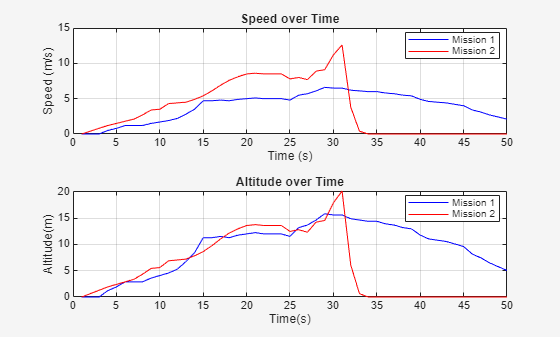

% Visualize the results (both overlayed)
bothplot = figure('Visible','off');
tiledlayout(2,1);
subplot(2,1,2);
nexttile;
plot(t, speed1, 'b', t, speed2, 'r');
title('Speed over Time');
xlabel('Time (s)');
ylabel('Speed (m/s)');
legend('Mission 1', 'Mission 2','Location','best');
grid on
nexttile;
plot(t,alt1,'b',t,alt2,'r');
title('Altitude over Time');
xlabel('Time(s)');
ylabel('Altitude(m)');
legend('Mission 1','Mission 2','Location','best');
grid on
saveas(bothplot,'Bothmiss','fig')

%Same plot setup, just mission 1
m1=figure('Visible','off');
tiledlayout(2,1);
subplot(2,1,2);
nexttile;
plot(t,speed1,'b');
title('Speed over Time');
xlabel('Time (s)');
ylabel('Speed (m/s)');
grid on;
nexttile;
plot(t,alt1,'b');
title('Altitude over Time');
xlabel('Time(s)');
ylabel('Altitude(m)');
grid on;
saveas(m1,'Miss1','fig')

%Plot everything with just mission 2
m2=figure('Visible','off');
tiledlayout(2,1);
subplot(2,1,2);
nexttile;
plot(t,speed2,'r');
title('Speed over Time');
xlabel('Time (s)');
ylabel('Speed (m/s)');
grid on;
nexttile;
plot(t,alt2,'r');
title('Altitude over Time');
xlabel('Time(s)');
ylabel('Altitude(m)');
grid on;
saveas(m2,'Miss2','fig')

% Create a scatter plot of speed vs altitude for both missions
sc=figure('Visible','off');
scatter(speed1, alt1, 'b');
hold on;
scatter(speed2, alt2, 'r');
title('Scatter Plot of Speed vs Altitude');
xlabel('Speed (m/s)');
ylabel('Altitude (m)');
legend('Mission 1', 'Mission 2', 'Location', 'best');
grid on;
hold off;
saveas(sc,'scatter','fig')

%Histogram of Speed and Altitude for each mission
h=figure('Visible','off');
tiledlayout(2,2);
subplot(2,2,1)
nexttile
histogram(speed1)
xlabel('Speed(m/s)')
title('Speed Distribution Mission 1')
grid on;
nexttile;
histogram(speed2)
xlabel('Speed (m/s')
title('Speed Distribution Mission 2')
grid on;
nexttile
histogram(alt1)
xlabel('Altitude(m)')
title('Altitude Distribution Mission 1')
grid on;
nexttile
histogram(alt2)
xlabel('Altitude(m)')
title('Altitude Distribution Mission 2')
grid on
saveas(h,'hist','fig')

%Time to create a dashboard so that the user can select which mission they
%want to view, and what types of data they want to view.
%set(bothplot,'Visible','on')
%set(m1,'Visible','on')
%set(m2,'Visible','on')
%set(sc,'Visible','on')
%set(h, 'visible', 'on'); 
choice = menu('What Mission data would you like to view?','Both Missions','Mission 1','Mission 2','Scatter Plot','Histogram','All Data');
switch choice 
    case 0 
        disp("Goodbye!")
    case 1
        open("Bothmiss.fig")
        set(bothplot,'Visible','on')
        
    case 2
        open("Miss1.fig")
        set(m1,'Visible','on')
        
    case 3
        open("Miss2.fig")
        set(m2,'Visible','on')
        
    case 4
        open("scatter.fig")
        set(sc,'Visible','on')
        
    case 5 
        open("hist.fig")
        set(h, 'visible', 'on'); 
        
    case 6
        open("Bothmiss.fig")
        open("Miss1.fig")
        open("Miss2.fig")
        open("scatter.fig")
        open("hist.fig")
        set(bothplot,'Visible','on')
        set(m1,'Visible','on')
        set(m2,'Visible','on')
        set(sc,'Visible','on')
        set(h, 'visible', 'on');
        
end 